# Tablice

Matlab stworzono, by pracować na tablicach/macierzach. Łatwo je tworzyć i wiele funkcji czy działań operuje na całych tabliach. Wektory i macierze wykorzystywane są do przechowywanie danych tego samego typu.

-    rozmiar macierzy to $r\times k$, gdzie $r$ to liczba rzędów a $k$ to liczba kolumn,

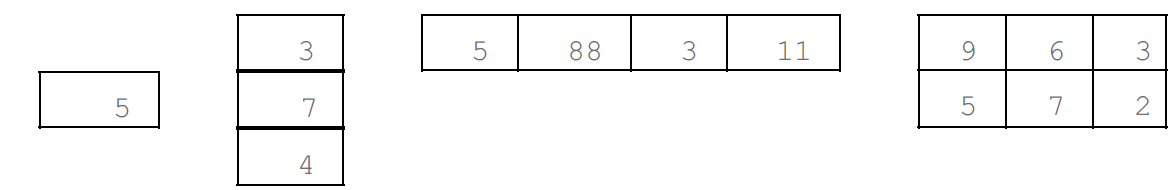

- **wektor** to tablica 1-wymiarowa: wektor kolumnowy ma jedną kolumnę i $n$ rzędów (rozmiar $n\times 1$); wektor rzędowy ma 1 wiersz i $n$ kolumn (rozmiar $1\times n$),

- **skalar** to liczba, czyli tablica o rozmiarze $1\times 1$.  

## Rozmiar tablicy

Można odczytać długość i rozmiar macierzy korzystając z odpowiednich funkcji` length()` i `size()`.  

vec = -2:1

vec =     -2    -1     0     1


length(vec)

ans = 4

size(vec)

ans =      1     4


Funkcja `size()` zwraca najpierw liczbę wierszy, potem liczbę kolumn. 

Uwaga: w matlabie można zadać wektor po lewej stronie równania przypisania wartości zmiennej.

mat = [1:3;5:7]'

mat =      1     5
     2     6
     3     7


[r c] = size(mat)   

r = 3

c = 2

Funkcja` length()` zwróci liczbę wierszy lub kolumn, wybierając większą wartość  

length(mat)

ans = 3

**Pytanie 1**: Jak utworzyć tablicę wypełnioną zerami o rozmiarze takim samym, jak tablicy `mat`.

zeros(size(mat))

ans =      0     0     0
     0     0     0


Funkcja `numel()` zwraca liczbę elementów tablicy.

vec = 9:-2:1
numel(vec)
mat = [3:2:7; 9 33 11]
numel(mat)

### Zmiana rozmiaru tablicy

Funkcja `reshape()` zmienia rozmiar tablicy 

mat = round(rand(3,4)*100)

Te 12 wartości można uporządkować jako tablice: $2\times 6$, $6\times 2$, $4\times 3$, $3\times 4$, $1\times 12$ i $12\times 1$. Funkcja `reshape() `zmienia kształt przechodząc po kolumnach od lewej do prawej:

reshape(mat,2,6)

W tym przykładzie tablica `mat` się nie zmienia. Zmieniona tablica przechowywana jest w zmiennej tymczasowej `ans`.

Funkcja` rot90()` obraca tablicę o ${90}^{\circ }$ w kierunku przeciwnym do ruchu wskazówek zegara. 

Uwaga: wynik jest inny, niż przy skorzystaniu z operatora '

rot90(mat)
mat'

Funkcja `rot90()` może mieć drugi argument określający, krotność ${90}^{\circ }$, o jaką ma być obrócona tablica. Ten argument może być ujemny, wtedy obrót następuje w przeciwnym kierunku.

 rot90(mat,2)
 rot90(mat,-1)

Funkcja `repmat(mat, m, n)` tworzy nową tablicę przez powtórzenie $m\times n$ tablicy `mat`. 

intmat = round(rand(2)*100)

Powtarzając tą tablicę 6 razy jako tablicę $3\times 2$ spowoduje powstanie tablicy:

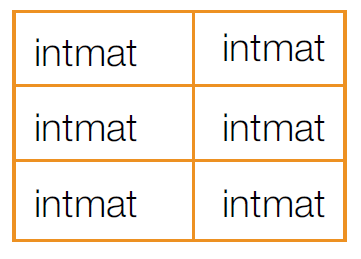

repmat(intmat,3,2)

## Działania funkcji na tablice i wektory

Tablicę lub wektor można podać jako argumet funkcji. Wtedy zostanie wykonana dana operacja na każdym elemencie tablicy czy wektora. Wektor powstały po zadziałaniu funkcji będzie mieć ten sam rozmiar, co wektor argument.

vec = -3:4
abs(vec)

mat = round(rand(2,3)*10-5)
abs(mat)

#### Pusty wektor

Pusty wektor, czyli taki, który nie zawiera żadnych wartości:

evec = []
length(evec)

Wzwykły sposób można dodać wartości do pustego wektora: 

evec = [evec 4]

Można to powtarzać wielokrotnie tworząc potrzebny wektor

evec = [evec 11]

Puste wektory wykorzystywane są do usunięcia elementów wektora 

vec = 1:5
vec(3) = []

Lub całych fragmentów wektora

vec = 1:8
vec(2:4) = []

Nie można usunąć pojedynczych elementów tablicy.

mat = [7 9 8; 4 6 5]

mat =      7     9     8
     4     6     5


mat(1,2) = []

A null assignment can have only one non-colon index.

Można usuwać wiersze lub kolumny.

mat(:,2) = []

mat =      7     8
     4     5


Jeśli skorzysta się z 1-elementowego indeksowania tablicy, wynikowa tablica zostanie przekszytałcona w wektor

mat = [7 9 8; 4 6 5]
mat(3) = []